# Symbolic Mathematics

## Symbolic Objects

The Symbolic Math Toolbox defines a new MATLAB data type called a symbolic object.

Internally, a symbolic object is a data structure that stores a string representation of the symbol. The Symbolic Math Toolbox uses symbolic objects to represent symbolic variables, expressions, and matrices.

The following example illustrates the difference between a standard MATLAB data type, such as double, and the corresponding symbolic object. The MATLAB command `sqrt(2)` returns a floating-point decimal number: 

sqrt(2)

ans =      1.414213562373095e+00

On the other hand, if you convert 2 to a symbolic object using the `sym` command, and then take its square root by entering

a = sqrt(sym(2))

$$a = \sqrt{2}$$

MATLAB gives the result $\sqrt 2$, using symbolic notation for the square root operation, without actually calculating a numerical value. MATLAB records this symbolic expression in the string that represents `2^(1/2)`. You can always obtain the numerical value of a symbolic object with the `double` command:

double(a)

ans =      1.414213562373095e+00

Notice that the result is indented in the command window, which tells you it has data type double. Symbolic results are not indented.

When you create a fraction involving symbolic objects, MATLAB records the numerator and denominator. For example:

sym(2)/sym(5)

$$ans = \frac{2}{5}$$

MATLAB performs arithmetic on symbolic objects differently than it does on standard data types. If you add two fractions that are of data type double, MATLAB gives the answer as a decimal fraction. For example:

2/5 + 1/3

ans =      7.333333333333334e-01

If you add the same fractions as symbolic objects, MATLAB finds their common denominator and combines them by the usual procedure for adding rational numbers:

sym(2)/sym(5) + sym(1)/sym(3)

$$ans = \frac{11}{15}$$

### Creating Symbolic Variables and Expressions

The `sym` command lets you construct symbolic variables and expressions. For example, the commands

x = sym('x')

$$x = x$$

a = sym('alpha')

$$a = \alpha$$

create a symbolic variable `x` that prints as `x` and a symbolic variable `a` that prints as $\alpha$.

Suppose you want to use a symbolic variable to represent the golden ratio $\rho=\frac{1+\sqrt 5}{2}$. The command `str2sym` achieves this goal:

rho = str2sym('(1 + sqrt(5))/2')

$$rho = \frac{\sqrt{5}}{2}+\frac{1}{2}$$

Now you can perform various mathematical operations on `rho`. For example,

f = rho^2 - rho - 1

$$f = {\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{2}-\frac{\sqrt{5}}{2}-\frac{3}{2}$$

You can simplify this answer by entering

simplify(f)

$$ans = 0$$

Now suppose you want to study the quadratic function $f = ax^2 + bx + c$. One approach is to enter the command

f = str2sym('a*x^2 + b*x + c')

$$f = a\,x^{2}+b\,x+c$$

which assigns the symbolic expression $a*x^2 + b*x + c$ to the variable `f`. However, in this case, the Symbolic Math Toolbox does not create variables corresponding to the terms of the expression, $a$ , $b$ , $c$ , and $x$ . To perform symbolic math operations (e.g., integration, differentiation, substitution, etc.) on `f`, you need to create the variables explicitly. A better alternative is to enter the commands

a = sym('a');
b = sym('b');
c = sym('c');
x = sym('x');

or simply

syms a b c x

Then enter

f = a*x^2 + b*x + c

$$f = a\,x^{2}+b\,x+c$$

In general, you can use `sym` or `syms` to create symbolic variables. We recommend you use `syms` because it requires less typing.

To create a symbolic expression that is a constant, you must use the `sym` command. For example, to create the expression whose value is 5, enter `f = sym(5)`. Note that the command `f = 5` does not define `f` as a symbolic expression.

If you set a variable equal to a symbolic expression, and then apply the `syms` command to the variable, MATLAB removes the previously defined expression from the variable. For example,

syms a b f
f

$$f = f$$

You can use the `syms` command to clear variables of definitions that you assigned to them previously in your MATLAB session. However, `syms` does not clear the properties of the variables in the Maple workspace.

clear f
f

Unrecognized function or variable 'f'.

#### The `symvar` Command

To determine what symbolic variables are present in an expression, use the `symvar` command. For example, given the symbolic expressions `f` and `g` defined by

syms a b n t x z
f = x^n; g = sin(a*t + b);

you can find the symbolic variables in `f` by entering

symvar(f)

$$ans = \left(\begin{array}{cc} n & x \end{array}\right)$$

Similarly, you can find the symbolic variables in `g` by entering

symvar(g)

$$ans = \left(\begin{array}{ccc} a & b & t \end{array}\right)$$

#### The `subs` Command

You can substitute a numerical value for a symbolic variable using the `subs` command. For example, to substitute the value `x = 2` in the symbolic expression, `f = 2*x^2 - 3*x + 1`

syms x;
f = 2*x^2 - 3*x + 1;
subs(f, 2)

$$ans = 3$$

To substitute a matrix `A` into the symbolic expression `f`, use the command `polyvalm(sym2poly(f), A)`, which replaces all occurrences of `x` by `A`, and replaces the constant term of `f` with the constant times an identity matrix.

When your expression contains more than one variable, you can specify the variable for which you want to make the substitution. For example, to substitute the value `x = 3` in the symbolic expression,

syms x y
f = x^2*y + 5*x*sqrt(y);
subs(f, x, 3)

$$ans = 9\,y+15\,\sqrt{y}$$

On the other hand, when substituting `y = 3`, we get

subs(f, y, 3)

$$ans = 3\,x^{2}+5\,\sqrt{3}\,x$$

If you do not specify a variable to substitute for, MATLAB chooses a default variable according to the following rule. For one-letter variables, MATLAB chooses the letter closest to `x` in the alphabet. If there are two letters equally close to `x`, MATLAB chooses the one that comes later in the alphabet. In the preceding function, `subs(f, 3)` returns the same answer as `subs(f, x, 3)`.

You can use the `symvar` command to determine the default variable. For example,

syms s t
g = s + t;
symvar(g, 1)

$$ans = t$$

#### Symbolic and Numeric Conversions

Consider the ordinary MATLAB quantity

t = 0.1;

The `sym` function has four options for returning a symbolic representation of the numeric value stored in `t`. The `'f'` option returns a symbolic floating-point representation

sym(t, 'f')

$$ans = \frac{3602879701896397}{36028797018963968}$$

The `'r'` returns the rational form

sym(t, 'r')

$$ans = \frac{1}{10}$$

This is the default setting for `sym`. That is, calling `sym` without a second argument is the same as using `sym` with the `'r'` option.

The third option `'e'` returns the rational form of `t` plus the difference between the theoretical rational expression for `t` and its actual (machine) floating-point value in terms of `eps` (the floating-point relative accuracy):

sym(t, 'e')

$$ans = \frac{\mathrm{eps}}{40}+\frac{1}{10}$$

The fourth option `'d'` returns the decimal expansion of `t` up to the number of significant digits specified by digits:

sym(t, 'd')

$$ans = 0.1$$

The default value of digits is 32 (hence, `sym(t,'d'`) returns a number with 32 significant digits), but if you prefer a shorter representation, use the `digits` command as follows:

digits(7)
sym(t,'d')

$$ans = 0.1$$

A particularly effective use of `sym` is to convert a matrix from numeric to symbolic form. The command `hilb(3)` generates the 3-by-3 Hilbert matrix:

A = hilb(3)

A =      1.000000000000000e+00     5.000000000000000e-01     3.333333333333333e-01
     5.000000000000000e-01     3.333333333333333e-01     2.500000000000000e-01
     3.333333333333333e-01     2.500000000000000e-01     2.000000000000000e-01


By applying `sym` to `A` you can obtain the symbolic (infinitely precise) form of the 3-by-3 Hilbert matrix:

A = sym(A)

$$A = \left(\begin{array}{ccc} 1 & \frac{1}{2} & \frac{1}{3}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} \end{array}\right)$$

#### Constructing Real and Complex Variables

The `sym` command allows you to specify the mathematical properties of symbolic variables by using the `'real'` option. That is, the statements

x = sym('x','real'); y = sym('y','real');

or more efficiently

syms x y real
z = x + 1i*y

$$z = x+y\,\mathrm{i}$$

create symbolic variables `x` and `y` that have the added mathematical property of being real variables. Specifically this means that the expression `f = x^2 + y^2 `is strictly nonnegative. Hence, `z` is a complex variable and can be manipulated as such,:

conj(x)

$$ans = x$$

conj(z)

$$ans = x-y\,\mathrm{i}$$

expand(z*conj(z))

$$ans = x^{2}+y^{2}$$

The `conj` command is the complex conjugate operator for the toolbox.

When you declare `x` to be real with the command `syms x real`, `x` becomes a symbolic object in the MATLAB workspace and a positive real variable in the Maple kernel workspace. If you later want to remove the real property from `x`, enter

syms x

### Creating functions

The sequence of commands

syms x y z
r = sqrt(x^2 + y^2 + z^2);
t = atan(y/x);
f = sin(x*y)/(x*y);

generates the symbolic expressions `r`, `t`, and `f`. You can use `diff`, `int`, `subs`, and other Symbolic Math Toolbox functions to manipulate such expressions.

#### Creating Abstract Functions

syms f(x)

Then `f` acts like `f(x)` and can be manipulated by the toolbox commands. For example, to construct the first difference ratio, type

syms x h
df = (subs(f, x, x+h) - f) / h 

$$df(x) = \frac{f\left(h+x\right)-f\left(x\right)}{h}$$

#### Creating Abstract Matrices

A circulant matrix has the property that each row is obtained from the previous one by cyclically permuting the entries one step forward. You can create the circulant matrix `A` whose elements are `a`, `b`, and `c`, using the commands

syms a b c
A = [a b c; b c a; c a b]

$$A = \left(\begin{array}{ccc} a & b & c\\ b & c & a\\ c & a & b \end{array}\right)$$

Since `A` is circulant, the sum over each row and column is the same. To check this for the first row and second column, enter the command

sum(A(1,:))

$$ans = a+b+c$$

simplify(sum(A(1,:)) == sum(A(:,2))) % This is a logical test

$$ans = \mathrm{TRUE}$$

Now replace the `(2,3)` entry of `A` with `beta` and the variable `b` with `alpha`:

syms alpha beta;
A(2,3) = beta;
A = subs(A,b,alpha)

$$A = \left(\begin{array}{ccc} a & \alpha & c\\ \alpha & c & \beta \\ c & a & \alpha \end{array}\right)$$

From this example, you can see that using symbolic objects is very similar to using regular MATLAB numeric objects.

### Simplifications and Substitutions

There are several functions that simplify symbolic expressions and are used to perform symbolic substitutions.

#### Simplifications

Here are three different symbolic expressions.

syms x
f = x^3-6*x^2+11*x-6

$$f = x^{3}-6\,x^{2}+11\,x-6$$

g = (x-1)*(x-2)*(x-3)

$$g = \left(x-1\right)\,\left(x-2\right)\,\left(x-3\right)$$

h = -6+(11+(-6+x)*x)*x

$$h = x\,\left(x\,\left(x-6\right)+11\right)-6$$

Here are their prettyprinted forms for use in the command window

pretty(f)

 3      2
x  - 6 x  + 11 x - 6



pretty(g)

(x - 1) (x - 2) (x - 3)



pretty(h)

x (x (x - 6) + 11) - 6



These expressions are three different representations of the same mathematical function, a cubic polynomial in `x`.

Each of the three forms is preferable to the others in different situations. The first form, `f`, is the most commonly used representation of a polynomial. It is simply a linear combination of the powers of `x`. The second form, `g`, is the factored form. It displays the roots of the polynomial and is the most accurate for numerical evaluation near the roots. But, if a polynomial does not have such simple roots, its factored form may not be so convenient. The third form, `h`, is the Horner, or nested, representation. For numerical evaluation, it involves the fewest arithmetic operations and is the most accurate for some other ranges of `x`.

The symbolic simplification problem involves the verification that these three expressions represent the same function. It also involves a less clearly defined objective — which of these representations is “the simplest”?

This toolbox provides several functions that apply various algebraic and trigonometric identities to transform one representation of a function into another, possibly simpler, representation. These functions are `collect`, `expand`, `horner`, `factor`, `combine` and `simplify`.

The statement `collect(f)` views `f` as a polynomial in its symbolic variable, say `x`, and collects all the coefficients with the same power of `x`. A second argument can specify the variable in which to collect terms if there is more than one candidate.

collect(f)

$$ans = x^{3}-6\,x^{2}+11\,x-6$$

syms t
collect((1+x)*t + x*t)

$$ans = \left(2\,t\right)\,x+t$$

collect((1+x)*t + x*t, t)

$$ans = \left(2\,x+1\right)\,t$$

The statement `expand(f)` distributes products over sums and applies other identities involving functions of sums as shown in the examples below.

expand(g)

$$ans = x^{3}-6\,x^{2}+11\,x-6$$

syms a b
expand(exp(a+b))

$$ans = {\mathrm{e}}^{a}\,{\mathrm{e}}^{b}$$

syms y
expand(cos(x+y))

$$ans = \cos\left(x\right)\,\cos\left(y\right)-\sin\left(x\right)\,\sin\left(y\right)$$

expand(cos(3*acos(x)))

$$ans = 4\,x^{3}-3\,x$$

The statement `horner(f)` transforms a symbolic polynomial `f` into its Horner, or nested, representation

horner(f)

$$ans = x\,\left(x\,\left(x-6\right)+11\right)-6$$

horner(g)

$$ans = x\,\left(x\,\left(x-6\right)+11\right)-6$$

If `f` is a polynomial with rational coefficients, the statement `factor(f)` expresses `f` as a product of polynomials of lower degree with rational coefficients. If `f` cannot be factored over the rational numbers, the result is `f` itself.

factor(f)

$$ans = \left(\begin{array}{ccc} x-3 & x-1 & x-2 \end{array}\right)$$

factor(h)

$$ans = \left(\begin{array}{ccc} x-3 & x-1 & x-2 \end{array}\right)$$

Here is another example involving factor:

factor(x^9-1)

$$ans = \left(\begin{array}{ccc} x-1 & x^{2}+x+1 & x^{6}+x^{3}+1 \end{array}\right)$$

factor(x^9+1)

$$ans = \left(\begin{array}{ccc} x+1 & x^{2}-x+1 & x^{6}-x^{3}+1 \end{array}\right)$$

As an aside at this point, factor can also factor symbolic objects containing integers.

N = sym(150);
factor(N)

$$ans = \left(\begin{array}{cccc} 2 & 3 & 5 & 5 \end{array}\right)$$

The `combine `statement combines terms of the same algebraic structure. A second argument can be specified indicating the target: `'atan'`, `'exp'`, `'gamma'`, `'log'`, `'sincos'`, or `'sinhcosh'`.

combine(2^x * 3^x)

$$ans = 6^{x}$$

combine(log(x) + log(y), 'log')

$$ans = \log\left(x\right)+\log\left(y\right)$$

syms x y positive
combine(log(x) + log(y), 'log')

$$ans = \log\left(x\,y\right)$$

The `simplify` function is a powerful, general purpose tool that applies a number of algebraic identities involving sums, integral powers, square roots and other fractional powers, as well as a number of functional identities involving trig functions, exponential and log functions, Bessel functions, hypergeometric functions, and the gamma function. Here are some examples.

simplify((1-x^2)/(1-x))

$$ans = x+1$$

simplify((1/a^3+6/a^2+12/a+8)^(1/3))

$$ans = {\left(\frac{{\left(2\,a+1\right)}^{3}}{a^{3}}\right)}^{1/3}$$

simplify(log(x*y))

$$ans = \log\left(x\,y\right)$$

simplify(exp(x) * exp(y))

$$ans = {\mathrm{e}}^{x+y}$$

simplify(cos(x)^2+sin(x)^2)

$$ans = 1$$

#### Substitutions

There are two functions for symbolic substitution: `subexpr` and `subs`.

To solve the equation `x^3+a*x+1 = 0` for `x`, we use the following commands

syms a b c d x
t = solve(a*x^3+b*x^2+c*x == 0, x)

$$t = \left(\begin{array}{c} 0\\ -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

The `subexpr` function allows you to save a common subexpression as well as the symbolic object rewritten in terms of the subexpressiona.

[r,s] = subexpr(t,'s')

$$r = \left(\begin{array}{c} 0\\ -\frac{b+s}{2\,a}\\ -\frac{b-s}{2\,a} \end{array}\right)$$

$$s = \sqrt{b^{2}-4\,a\,c}$$

### Variable-Precision Arithmetic

There are three different kinds of arithmetic operations in this toolbox:

- Numeric Rational VPA

- MATLAB floating-point arithmetic

- Exact symbolic arithmetic variable-precision arithmetic

For example, the MATLAB statements use numeric computation

format long
1/2+1/3

ans =    0.833333333333333

The Symbolic Math Toolbox, uses symbolic computation to yield

sym(1/2)+1/3

$$ans = \frac{5}{6}$$

And, also with the toolbox, the statements

digits(25)
vpa(str2sym('1/2+1/3'))

$$ans = 0.8333333333333333333333333$$

use variable-precision arithmetic.

The floating-point operations used by numeric arithmetic are the fastest of the three, and require the least computer memory, but the results are not exact. The number of digits in the printed output of MATLAB double quantities is controlled by the format statement, but the internal representation is always the eight-byte floating-point representation provided by the particular computer hardware.

In the computation of the numeric result above, there are actually three roundoff errors, one in the division of 1 by 3, one in the addition of 1/2 to the result of the division, and one in the binary to decimal conversion for the printed output. On computers that use IEEE floating-point standard arithmetic, the resulting internal value is the binary expansion of 5/6, truncated to 53 bits. This is approximately 16 decimal digits. But, in this particular case, the printed output shows only 15 digits.

The symbolic operations used by rational arithmetic are potentially the most expensive of the three, in terms of both computer time and memory. The results are exact, as long as enough time and memory are available to complete the computations.

Variable-precision arithmetic falls in between the other two in terms of both cost and accuracy. A global parameter, set by the function digits, controls the number of significant decimal digits. Increasing the number of digits increases the accuracy, but also increases both the time and memory requirements. The default value of digits is 32, corresponding roughly to floating-point accuracy.

The `sym` function converts a double matrix to its symbolic form. For example, if the double matrix `A` is

A = [1.1 1.2 1.3
     2.1 2.2 2.3
     3.1 3.2 3.3]

A =    1.100000000000000   1.200000000000000   1.300000000000000
   2.100000000000000   2.200000000000000   2.300000000000000
   3.100000000000000   3.200000000000000   3.300000000000000


 S = sym(A)

$$S = \left(\begin{array}{ccc} \frac{11}{10} & \frac{6}{5} & \frac{13}{10}\\ \frac{21}{10} & \frac{11}{5} & \frac{23}{10}\\ \frac{31}{10} & \frac{16}{5} & \frac{33}{10} \end{array}\right)$$

For this matrix `A`, it is possible to discover that the elements are the ratios of small integers, so the symbolic representation is formed from those integers. On the other hand, the statement

 E = [exp(1) (1+sqrt(5))/2; log(3) rand]

E =    2.718281828459046   1.618033988749895
   1.098612288668110   0.794284540683907


returns a matrix whose elements are not the ratios of small integers,

 sym(E)

$$ans = \left(\begin{array}{cc} \frac{3060513257434037}{1125899906842624} & \frac{910872158600853}{562949953421312}\\ \frac{2473854946935173}{2251799813685248} & \frac{3577139561450189}{4503599627370496} \end{array}\right)$$

The `vpa` function generates the representation that is used with variable-precision arithmetic. For example, if you apply `vpa` to the matrix `S` defined in the preceding section

digits(4)
vpa(S)

$$ans = \left(\begin{array}{ccc} 1.1 & 1.2 & 1.3\\ 2.1 & 2.2 & 2.3\\ 3.1 & 3.2 & 3.3 \end{array}\right)$$

Applying `vpa` to the matrix `E` yields

digits(25)
F = vpa(E)

$$F = \left(\begin{array}{cc} 2.718281828459045534884808 & 1.618033988749894902525739\\ 1.098612288668109560063613 & 0.7942845406839069699600486 \end{array}\right)$$

To convert a rational or variable-precision number to its MATLAB floating-point representation, use the `double` function.

double(sym(E))

ans =    2.718281828459046   1.618033988749895
   1.098612288668110   0.794284540683907


double(vpa(E))

ans =    2.718281828459046   1.618033988749895
   1.098612288668110   0.794284540683907


In the example, both `double(sym(E))` and `double(vpa(E))` return `E`.

## Symbolic Calculus

### Limits

The fundamental idea in calculus is to make calculations on functions as a variable “gets close to” or approaches a certain value. Recall that the definition of the derivative is given by a limit


$$\textsf D f\left(x\right) = \lim_{h\rightarrow 0}\frac{f\left(x+h\right)-f\left(x\right)}{h}$$


provided this limit exists. The Symbolic Math Toolbox enables you to calculate the limits of functions directly.

syms h n x
limit( (cos(x+h) - cos(x))/h,h,0 )

$$ans = -\sin\left(x\right)$$

limit( (1 + x/n)^n,n,inf )

$$ans = {\mathrm{e}}^{x}$$

These examples illustrate two of the most important limits in mathematics: the derivative (in this case of $cos x$) and the exponential function.

#### One-Sided Limits

You can also calculate one-sided limits with the Symbolic Math Toolbox. For example, you can calculate the limit of $\frac{x}{|x|}$ as $x$ approaches $0$ from the left or from the right.

limit(x/abs(x),x,0,'left')

$$ans = -1$$

limit(x/abs(x),x,0,'right')

$$ans = 1$$

limit(x/abs(x),x,0)

$$ans = \mathrm{NaN}$$

Since the limit from the left does not equal the limit from the right, the two- sided limit does not exist. In the case of undefined limits, MATLAB returns `NaN`.

### Differentiation

To illustrate how to take derivatives using the Symbolic Math Toolbox, first create a symbolic expression:

syms x
f = sin(5*x);

The command `diff(f)` differentiates `f` with respect to `x`:

diff(f)

$$ans = 5\,\cos\left(5\,x\right)$$

As another example, let

g = exp(x)*cos(x)

$$g = {\mathrm{e}}^{x}\,\cos\left(x\right)$$

and differentiate `g`:

diff(g)

$$ans = {\mathrm{e}}^{x}\,\cos\left(x\right)-{\mathrm{e}}^{x}\,\sin\left(x\right)$$

To take the second derivative of `g`, enter

diff(g,2)

$$ans = -2\,{\mathrm{e}}^{x}\,\sin\left(x\right)$$

You can get the same result by taking the derivative twice:

diff(diff(g)) 

$$ans = -2\,{\mathrm{e}}^{x}\,\sin\left(x\right)$$

In this example, MATLAB automatically simplifies the answer. However, in some cases, MATLAB might not simply an answer, in which case you can use the `simplify` command. 

Note that to take the derivative of a constant, you must first define the constant as a symbolic expression. For example,

c = sym('5');
diff(c)

$$ans = 0$$

Attention, you get

diff(5)

ans =
     []


because 5 is not a symbolic expression.

#### Derivatives of Expressions with Several Variables

To differentiate an expression that contains more than one symbolic variable, you must specify the variable that you want to differentiate with respect to. The `diff` command then calculates the partial derivative of the expression with respect to that variable. For example,

syms s t
f = sin(s*t);
diff(f,t)

$$ans = s\,\cos\left(s\,t\right)$$

calculates the partial derivative $\frac{\partial f}{\partial t}$. To differentiate `f` with respect to the variable `s`, enter 

diff(f,s)

$$ans = t\,\cos\left(s\,t\right)$$

If you do not specify a variable to differentiate with respect to, MATLAB chooses a default variable by the variable selection rule. For one-letter variables, the default variable is the letter closest to `x` in the alphabet. In the preceding example, `diff(f)` takes the derivative of `f` with respect to `t` because `t` is closer to `x` in the alphabet than `s` is.

To calculate the second derivative of `f` with respect to `t`, enter 

diff(f,t,2)

$$ans = -s^{2}\,\sin\left(s\,t\right)$$

Note that `diff(f,2)` returns the same answer because `t` is the default variable.

The `diff` function can also take a symbolic matrix as its input. In this case, the differentiation is done element-by-element. Consider the example

syms a x
A = [cos(a*x),sin(a*x);-sin(a*x),cos(a*x)];
diff(A)

$$ans = \left(\begin{array}{cc} -a\,\sin\left(a\,x\right) & a\,\cos\left(a\,x\right)\\ -a\,\cos\left(a\,x\right) & -a\,\sin\left(a\,x\right) \end{array}\right)$$

#### Gradient

The vector containing the derivatives with respect to all variables of a function is called the *gradient*.


$$\nabla f = \pmatrix{\frac{\partial f}{\partial x}\cr\frac{\partial f}{\partial y}\cr \frac{\partial f}{\partial z}}$$


You can use the function `gradient` to evaluate this vector, eg.

syms x y z
f = x^2*y+z^3;
gradient(f)

$$ans = \left(\begin{array}{c} 2\,x\,y\\ x^{2} \end{array}\right)$$

#### Jacobian

You can also perform differentiation of a column vector with respect to a row vector. Consider the transformation from Euclidean $(x, y, z)$ to spherical $(r, \phi, \theta)$ coordinates as given by 


$$\begin{cases}
x =& r\cos\phi\sin\theta\\
y =& r\sin\phi\sin\theta\\
z =& r\cos\theta
\end{cases}$$


To calculate the Jacobian matrix, $J=\frac{(x,y,z)}{(r,\phi,\theta)}$, of this transformation, use the `jacobian` function. For the purposes of toolbox syntax, use `t` for $\theta$ and `f` for $\phi$:

syms r
f = sym('phi');
t = sym('theta');
x = r*cos(f)*sin(t);
y = r*sin(f)*sin(t);
z = r*cos(t);
J = jacobian([x; y; z],[r, f, t])

$$J = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\sin\left(\theta \right) & -r\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & r\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & r\,\cos\left(\varphi \right)\,\sin\left(\theta \right) & r\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \cos\left(\theta \right) & 0 & -r\,\sin\left(\theta \right) \end{array}\right)$$

To calculate the Jacobian of the transformation, we enter

simplify(det(J))

$$ans = -r^{2}\,\sin\left(\theta \right)$$

Notice that the first argument of the `jacobian` function must be a column vector and the second argument a row vector. Moreover, since the determinant of the Jacobian is a rather complicated trigonometric expression, you can use the `simplify` command to make trigonometric substitutions and reductions (simplifications).

### Symbolic Summation

You can compute symbolic summations, when they exist, by using the `symsum` command. For example, the p-series


$$1 + \frac{1}{2^2}+\frac{1}{3^2}+\cdots$$


sums to $\frac{\pi^2}{6}$, while the geometric series


$$1 + x + x^2 + \cdots$$


sums to $\frac{1}{1-x}$, provided $x < 1$:

syms x k
s1 = symsum(1/k^2,1,inf)

$$s1 = \frac{\pi^{2}}{6}$$

s2 = symsum(x^k,k,0,inf)

$$s2 = \left\{ \begin{array}{cl} \infty & \text{ if }1\leq x\\ -\frac{1}{x-1} & \text{ if }\left|x\right|<1 \end{array}\right.$$

### Integration

If `f` is a symbolic expression, then `int(f)` attempts to find another symbolic expression, `F`, so that `diff(F) = f`. That is, `int(f)` returns the indefinite integral or antiderivative of `f` (provided one exists in closed form). Similar to differentiation, `int(f,x)` uses the symbolic object `x` as the variable of integration, rather than the variable determined by `symvar`.

syms x n a b t
int(x^n)

$$ans = \left\{ \begin{array}{cl} \log\left(x\right) & \text{ if }n=-1\\ \frac{x^{n+1}}{n+1} & \text{ if }n\neq -1 \end{array}\right.$$

int(sin(2*x),0,pi/2)

$$ans = 1$$

g = cos(a*t+b);
int(g, t)

$$ans = \frac{\sin\left(b+a\,t\right)}{a}$$

In contrast to differentiation, symbolic integration is a more complicated task. A number of difficulties can arise in computing the integral:

- The antiderivative, `F`, may not exist in closed form.

- The antiderivative may define an unfamiliar function.

- The antiderivative may exist, but the software can’t find the it.

- The software could find the antiderivative on a larger computer, but runs out of time or memory on the available machine.

Nevertheless, in many cases, MATLAB can perform symbolic integration successfully.

int(exp(-x^2))

$$ans = \frac{\sqrt{\pi }\,\mathrm{erf}\left(x\right)}{2}$$

In the last example, $\mathrm e^{-x^2}$, there is no formula for the integral involving standard calculus expressions, such as trigonometric and exponential functions. In this case, MATLAB returns an answer in terms of the error function `erf`.

If MATLAB is unable to find an answer to the integral of a function `f`, it just returns `int(f)`.

Definite integration is also possible. The commands `int(f,a,b)` and `int(f,v,a,b)` are used to find a symbolic expression for

$\int_a^bf(x)\,\mathrm d x$ and $\int_a^bf(v)\,\mathrm d v$ respectively.

int(exp(-x^2),0,inf)

$$ans = \frac{\sqrt{\pi }}{2}$$

double(ans)

ans =    0.886226925452758

#### Integration with Real Parameters

One of the subtleties involved in symbolic integration is the “value” of various parameters. For example, if a is any positive real number, the expression $\mathrm e^{-ax^2}$ is the positive, bell shaped curve that tends to $0$ as $x$ tends to $\pm\infty$. You can create an example of this curve, for `a = 0.5`, using the following commands:

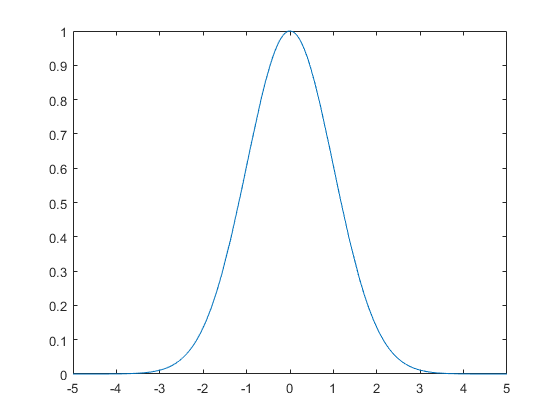

syms x
a = sym(1/2);
f = exp(-a*x^2);
fplot(f)

However, if you try to calculate the integral $\int_{-\infty}^\infty \mathrm e^{-ax^2}\,\mathrm d x$ without assigning a value to $a$, MATLAB assumes that $a$ represents a complex number, and therefore returns a complex answer.

syms x a
f = exp(-a*x^2);
int(f,-inf,inf)

$$ans = \begin{array}{l} \left\{ \begin{array}{cl} \infty & \text{ if }a<0\\ \frac{\sqrt{\pi }}{\sqrt{a}} & \text{ if }0\leq \mathrm{real}\left(a\right)\vee \left(\left(\text{angle}\left(a\right)\in \sigma_{2}\vee \text{angle}\left(a\right)\in \sigma_{1}\right)\wedge a\neq 0\right)\\ \int_{-\infty }^{\infty }{\mathrm{e}}^{-x^{2}\,a}\mathrm{d}x & \text{ if }\mathrm{real}\left(a\right)<0\wedge \text{angle}\left(a\right)\notin \sigma_{2}\wedge \text{angle}\left(a\right)\notin \sigma_{1}\wedge \neg a<0 \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\left\{-\frac{\pi }{2},\frac{\pi }{2}\right\}\\ \sigma_{2}=\left(-\frac{\pi }{2},\frac{\pi }{2}\right) \end{array}$$

The case when $a$ is a positive real number, you can calculate the integral as follows:

syms a positive;
int(f,x,-inf,inf)

$$ans = \frac{\sqrt{\pi }}{\sqrt{a}}$$

If you want to calculate the integral for any real number $a$, not necessarily positive, you can declare `a` to be real with the following commands:

syms a real
int(f,x,-inf,inf)

$$ans = \left\{ \begin{array}{cl} \frac{\sqrt{\pi }}{\sqrt{a}} & \text{ if }0<a\\ \infty & \text{ if }a\leq 0 \end{array}\right.$$

### Taylor Series

The following statements return

syms x
f = 1/(5+4*cos(x));
T = taylor(f,'Order', 8)

$$T = \frac{49\,x^{6}}{131220}+\frac{5\,x^{4}}{1458}+\frac{2\,x^{2}}{81}+\frac{1}{9}$$

which is all the terms up to, but not including, order eight in the Taylor series for $f(x)=\frac{1}{5+4\cos x}$:


$$T\left(x\right)=\sum_{n=0}^7\frac{1}{n!}f^{\left(n\right)}\left(x-a\right)^n$$


Technically, `T` is a Maclaurin series, since its basepoint is `a = 0`.

These commands

syms x
g = exp(x*sin(x));
t = taylor(g,x,2,'Order',12);

generate the first 12 nonzero terms of the Taylor series for `g` about `x = 2`. Next, plot these functions together to see how well this Taylor approximation compares to the actual function `g`:

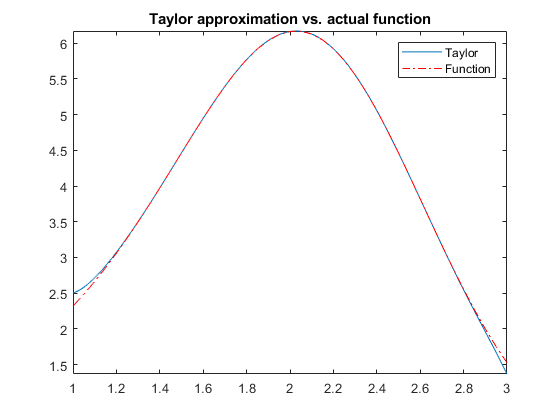

xd = 1:0.05:3; yd = subs(g,x,xd);
fplot(t, [1,3]); hold on;
plot(xd, yd, 'r-.')
title('Taylor approximation vs. actual function'); 
legend('Taylor','Function')

## Symbolic Linear Algebra

### Basic Algebraic Operations

Basic algebraic operations on symbolic objects are the same as operations on MATLAB objects of class double. This is illustrated in the following example.

The *Givens transformation* produces a plane rotation through the angle $\phi$. The statements

t = sym('phi');
G = [cos(t) sin(t); -sin(t) cos(t)]

$$G = \left(\begin{array}{cc} \cos\left(\varphi \right) & \sin\left(\varphi \right)\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

create this transformation matrix.

Applying the Givens transformation twice should simply be a rotation through twice the angle. The corresponding matrix can be computed by multiplying `G` by itself or by raising `G` to the second power.

A = G^2

$$A = \left(\begin{array}{cc} {\cos\left(\varphi \right)}^{2}-{\sin\left(\varphi \right)}^{2} & 2\,\cos\left(\varphi \right)\,\sin\left(\varphi \right)\\ -2\,\cos\left(\varphi \right)\,\sin\left(\varphi \right) & {\cos\left(\varphi \right)}^{2}-{\sin\left(\varphi \right)}^{2} \end{array}\right)$$

A = simplify(A)

$$A = \left(\begin{array}{cc} \cos\left(2\,\varphi \right) & \sin\left(2\,\varphi \right)\\ -\sin\left(2\,\varphi \right) & \cos\left(2\,\varphi \right) \end{array}\right)$$

The Givens rotation is an orthogonal matrix, so its transpose is its inverse. Confirming this by

I = transpose(G) * G

$$I = \left(\begin{array}{cc} {\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2} & 0\\ 0 & {\cos\left(\varphi \right)}^{2}+{\sin\left(\varphi \right)}^{2} \end{array}\right)$$

simplify(I)

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

### Linear Algebraic Operations

The following examples show to do several basic linear algebraic operations using the Symbolic Math Toolbox.

The command

H = hilb(3)

H =    1.000000000000000   0.500000000000000   0.333333333333333
   0.500000000000000   0.333333333333333   0.250000000000000
   0.333333333333333   0.250000000000000   0.200000000000000


The computed elements of `H` are floating-point numbers that are the ratios of small integers. Indeed, `H` is a MATLAB array of class double. Converting `H` to a symbolic matrix

H = sym(H)

$$H = \left(\begin{array}{ccc} 1 & \frac{1}{2} & \frac{1}{3}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} \end{array}\right)$$

This allows subsequent symbolic operations on `H` to produce results that correspond to the infinitely precise Hilbert matrix, `sym(hilb(3))`, not its floating-point approximation, `hilb(3)`. Therefore,

inv(H)

$$ans = \left(\begin{array}{ccc} 9 & -36 & 30\\ -36 & 192 & -180\\ 30 & -180 & 180 \end{array}\right)$$

and

det(H)

$$ans = \frac{1}{2160}$$

You can use the backslash operator to solve a system of simultaneous linear equations. For example:

b = [1 1 1]';
x = H\b    % Solve Hx = b

$$x = \left(\begin{array}{c} 3\\ -24\\ 30 \end{array}\right)$$

All three of these results, the inverse, the determinant, and the solution to the linear system, are the exact results corresponding to the infinitely precise, rational, Hilbert matrix.

An interesting example, which the following code shows, is to find a value `s` for `H(1,1)` that makes `H` singular.

syms s
H(1,1) = s;
Z = det(H)

$$Z = \frac{s}{240}-\frac{1}{270}$$

sol = solve(Z)

$$sol = \frac{8}{9}$$

Then

H = subs(H,s,sol);

Now,

det(H)

$$ans = 0$$

and

inv(H)

$$ans = \left(\begin{array}{ccc} \infty & \infty & \infty \\ \infty & \infty & \infty \\ \infty & \infty & \infty \end{array}\right)$$

### Eigenvalues

The symbolic eigenvalues of a square matrix `A` or the symbolic eigenvalues and eigenvectors of `A` are computed, respectively, using the commands `E = eig(A)` and `[V,E] = eig(A)`.

The eigenvalues of `A` are the zeros of the characteristic polynomial of `A`, i.e. `det(A-x*I)`, which is computed by `poly(A)`.

The matrix `H` from the last section provides a nice example:

H

$$H = \left(\begin{array}{ccc} \frac{8}{9} & \frac{1}{2} & \frac{1}{3}\\ \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\ \frac{1}{3} & \frac{1}{4} & \frac{1}{5} \end{array}\right)$$

The matrix is singular, so one of its eigenvalues must be zero. The statement

[T,E] = eig(H)

$$T = \left(\begin{array}{ccc} \frac{3}{10} & \frac{218}{285}-\frac{4\,\sqrt{12589}}{285} & \frac{4\,\sqrt{12589}}{285}+\frac{218}{285}\\ -\frac{6}{5} & \frac{292}{285}-\frac{\sqrt{12589}}{285} & \frac{\sqrt{12589}}{285}+\frac{292}{285}\\ 1 & 1 & 1 \end{array}\right)$$

$$E = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & \frac{32}{45}-\frac{\sqrt{12589}}{180} & 0\\ 0 & 0 & \frac{\sqrt{12589}}{180}+\frac{32}{45} \end{array}\right)$$

produces the matrices `T` and `E`. The columns of `T` are the eigenvectors of `H`.

The first eigenvalue is zero. The eigen values are the result of solving the characteristic polynomial:

p = charpoly(H)

$$p = \left(\begin{array}{cccc} 1 & -\frac{64}{45} & \frac{253}{2160} & 0 \end{array}\right)$$

roots(p)

$$ans = \left(\begin{array}{c} 0\\ \frac{32}{45}-\frac{\sqrt{12589}}{180}\\ \frac{\sqrt{12589}}{180}+\frac{32}{45} \end{array}\right)$$

Closed form symbolic expressions for the eigenvalues are possible only when the characteristic polynomial can be expressed as a product of rational polynomials of degree four or less. 

## Symbolic Solving Equations

### Solving Algebraic Equations

If `S` is a symbolic expression, `solve(S)` attempts to find values of the symbolic variable in `S` for which `S` is zero. For example,

syms a b c x
S = a*x^2 + b*x + c;
solve(S)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

The answer is stored in a symbolic vector whose elements are the two solutions.

If you want to solve for a specific variable, you must specify that variable as an additional argument. For example, if you want to solve `S` for `b`, use the command

b = solve(S,b)

$$b = -\frac{a\,x^{2}+c}{x}$$

Note that these examples assume equations of the form `f(x) = 0`. If you need to solve equations of the form `f(x) = q(x)` , you must use `==`. In particular, the command

s = solve(cos(2*x)+sin(x)==1)

$$s = \left(\begin{array}{c} 0\\ \frac{\pi }{6}\\ \frac{5\,\pi }{6} \end{array}\right)$$

returns a vector with three solutions.

### Several Algebraic Equations

This section explains how to solve systems of equations using the Symbolic Math Toolbox. As an example, suppose you have the system


$$\begin{cases}
x^2y^2&=0\\
x-\frac{y}{2}&=0
\end{cases}$$


and you want to solve for $x$ and $y$. 

syms x y alpha
[x,y] = solve(x^2*y^2, x-y/2-alpha)

$$x = \left(\begin{array}{c} \alpha \\ 0 \end{array}\right)$$

$$y = \left(\begin{array}{c} 0\\ -2\,\alpha \end{array}\right)$$

Changing the equations to

syms x y
[x, y] = solve(x^2*y^2==1, x-y/2-alpha)

$$x = \left(\begin{array}{c} \frac{\alpha }{2}-\frac{\sqrt{\alpha^{2}-2}}{2}\\ \frac{\alpha }{2}-\frac{\sqrt{\alpha^{2}+2}}{2}\\ \frac{\alpha }{2}+\frac{\sqrt{\alpha^{2}-2}}{2}\\ \frac{\alpha }{2}+\frac{\sqrt{\alpha^{2}+2}}{2} \end{array}\right)$$

$$y = \left(\begin{array}{c} -\alpha -\sqrt{\alpha^{2}-2}\\ -\alpha -\sqrt{\alpha^{2}+2}\\ \sqrt{\alpha^{2}-2}-\alpha \\ \sqrt{\alpha^{2}+2}-\alpha \end{array}\right)$$

produces four distinct solutions.

Since you did not specify the dependent variables, `solve` uses `symvar` to determine the variables.

This way of assigning output from solve is quite successful for “small” systems. Plainly, if you had, say, a 10-by-10 system of equations, typing `[x1,x2,x3,x4,x5,x6,x7,x8,x9,x10] = solve(...)` is both awkward and time consuming. To circumvent this difficulty, solve can return a structure whose fields are the solutions. In particular, consider the system


$$\begin{cases}
u^2-v^2 &= a^2\\
u + v &= 1\\
a^2-2a &= 3
\end{cases}$$


syms u v a
S = solve(u^2-v^2 == a^2, u + v == 1, a^2-2*a == 3)

S = struct with fields:
    a: [2×1 sym]
    u: [2×1 sym]
    v: [2×1 sym]

The solutions for a reside in the “a-field” of `S`. That is, 

S.a

$$ans = \left(\begin{array}{c} -1\\ 3 \end{array}\right)$$

Similar comments apply to the solutions for `u` and `v`. The structure `S` can now be manipulated by field and index to access a particular portion of the solution. For example, if you want to examine the second solution, you can use the following statement

s2 = [S.a(2), S.u(2), S.v(2)]

$$s2 = \left(\begin{array}{ccc} 3 & 5 & -4 \end{array}\right)$$

The following statement

M = [S.a, S.u, S.v]

$$M = \left(\begin{array}{ccc} -1 & 1 & 0\\ 3 & 5 & -4 \end{array}\right)$$

creates a matrix whose rows comprise the distinct solutions of the system.

Linear systems of simultaneous equations can also be solved using matrix division. For example,

syms u v x y
S = solve(x+2*y-u, 4*x+5*y-v);
s = [S.x;S.y]

$$s = \left(\begin{array}{c} \frac{2\,v}{3}-\frac{5\,u}{3}\\ \frac{4\,u}{3}-\frac{v}{3} \end{array}\right)$$

and

A = [1 2; 4 5];
b = [u; v];
z = A\b

$$z = \left(\begin{array}{c} \frac{2\,v}{3}-\frac{5\,u}{3}\\ \frac{4\,u}{3}-\frac{v}{3} \end{array}\right)$$

Thus `s` and `z` produce the same solution, although the results are assigned to different variables.